# Inverted Pendulum

clear all, clc, close all
%set(groot,'defaultFigurePosition',[0 0 900 900])

## Data

L = 0.3; % pendulum length (m)
M = 0.5; % mass of cart (kg)
m = 0.2; % mass of pendulum (kg)
b = 0.1; % friction coefficient for cart
max_F = 10; % max allowed force (N)
rail_length = 1;  % length of the rail
cart_length = 0.2; % length of the cart
I = 0.006; % traagheidsmoment
g = 9.81; % valversnelling

## Matrices opstellen

N = I*(M+m) + M*m*L^2;
A = [0 1 0 0;
    0 -(I+m*L^2)*b/N m^2*g*L^2/N 0;
    0 0 0 1;
    0 -m*L*b/N m*g*L*(M+m)/N 0];
B = [0;
    (I+m*L^2)/N;
    0;
    m*L/N];
C = [1 0 0 0;
    0 0 1 0];
D = [0;
    0];
states = {'x' 'v' 'theta' 'w'};
inputs = {'u'};
outputs = {'x'; 'theta'};
S = ss(A,B,C,D,'statename',states,'inputname',inputs,'outputname',outputs);
% Kleine coeff nog naar 0 zetten


## Controleerbaarheid

rank(ctrb(A,B)) == 4

ans = logical
   1


## Observeerbaarheid

rank(obsv(A,C)) == 4

ans = logical
   1


## Classical Controller

Ts = 0.05; % Sample time
Sd = c2d(S,Ts); % Discretiseren
Sdtf = tf(Sd); % We nemen de transferfunctie zodat we verder kunnen werken
% met enkel de transferfunctie van theta => SISO
ps = pole(Sdtf(2)) % Het berekenen van de polen voor theta

ps =     1.3210
    0.9929
    0.7555


zs = zero(Sdtf(2)) % Het berekenen van de nulpunten voor theta

zs =     1.0000
   -0.9970


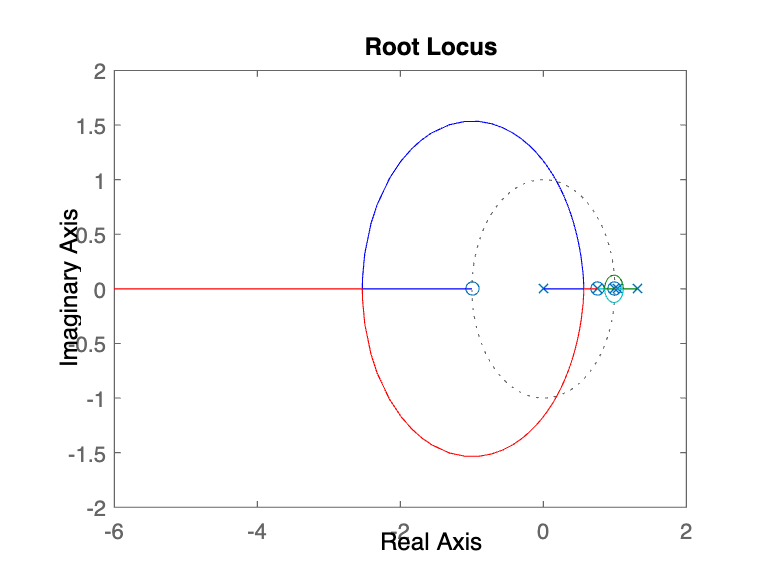

Rd = zpk([ps(2:end)],[0,1.04],48.1,Ts); % Implementatie van een eerste PID
% Nulpunten:
%   Nulpunten leggen op de polen binnen de eenheidscirkel zodat ze niet meer
%   zullen bewegen voor een variabele gain. Op de buitenste wordt er geen
%   nulpunt gelegd zodat het systeem kan gestabiliseerd worden.
% 
% Polen:
%   Er wordt een pool in 1.04 (arbitrair, maar wel nog steeds tussen de rechts uiterste pool
%   en het rechtse uiterste nulpunt) geplaatst. Die pool zal ervoor zorgen
%   dat de rootlocus wijzigt. Door de nieuwe vorm van de rootlocus is het
%   mogelijk adhv de gain de polen binnen de eenheidscirkel te plaatsen.
%   Door het criterium X hebben we een extra pool nodig. We plaatsen de
%   pool in 0 zodat we een snelle pool hebben. Het voordeel van de snelle
%   pool.
% 
% Gain:
%   We wensen de polen binnen de eenheidscirkel te plaatsen en kiezen
%   ervoor om deze eveneens op de reële as te laten vallen teneinde geen
%   imaginair component te verkrijgen. Daardoor wordt het oscillair gedrag
%   vermeden. Om de waarde van de gain te bepalen werd de rootlocus geplot
%   en de gain bepaald op de positie waar de twee rechtse krommes elkaar
%   binnen de eenheidscirkel raken.
rlocus(Rd*Sd(2))

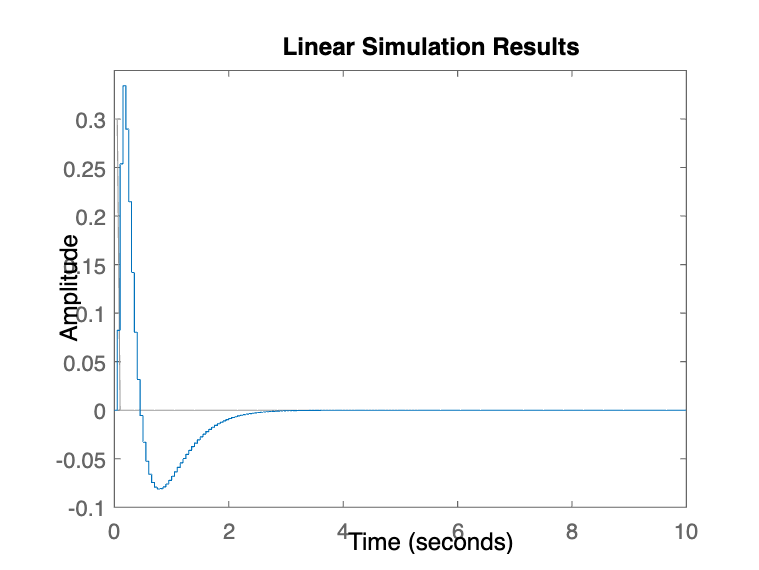

t = 0:Ts:10;
% Er worden geen impulsen of stappen aangelegd aangezien de hoek in
% realiteit niet zo'n verloop heeft. Daarom wordt gebruikgemaakt van lsim.
lsim(feedback(Rd*Sdtf(2),1),[0.3 0.3 zeros(1,length(t)-2)],t)

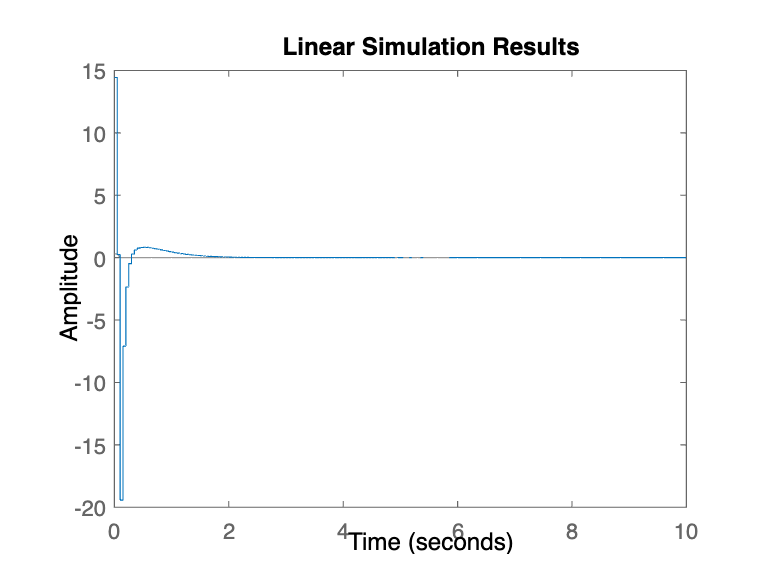

lsim(feedback(Rd,Sdtf(2)),[0.3 0.3 zeros(1,length(t)-2)],t)

SdCl_1stLoop = minreal(feedback(Rd*Sdtf,[0 1]))

SdCl_1stLoop =
 
  From input "u" to output...
        0.10914 (z+0.997) (z-0.7807) (z-1.281)
   x:  ----------------------------------------
       (z-1) (z-0.3718) (z^2 - 1.715z + 0.7354)
 
                0.27425 (z+0.997) (z-1)
   theta:  ----------------------------------
           (z-0.3718) (z^2 - 1.715z + 0.7354)
 
Sample time: 0.05 seconds
Discrete-time zero/pole/gain model.



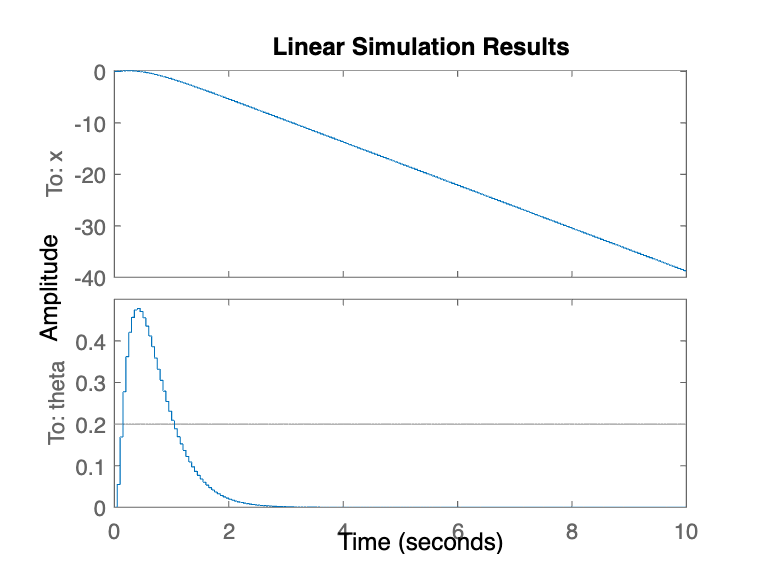

% Minreal vereenvoudigt de uitdrukking om het overzicht te bewaren.
% Enkel een feedback plaatsen op de hoek door [0 1]
lsim(minreal(feedback(Rd*Sdtf,[0 1])),[0.2 0.2 zeros(1,length(t)-2)],t)